# CS229 - Machine Learning

## Project

## Load Data

close all
clear
clc
warning('off','all')
rng default

Trainning_Data_Table = readtable('Trainning_Data.csv');
Trainning_Data = table2array(Trainning_Data_Table);
y_train = Trainning_Data(:, 4);
x_train = Trainning_Data(:, [2, 3, 5, 6, 7, 8, 9, 10, 11, 12]);
dates_train = Trainning_Data(:, 1);

### Train Gaussian Process with Various Kernels - Unoptimized

% Fit Gaussian Process with exponential Kernel
gprMdl_1 = fitrgp(x_train, y_train,'KernelFunction','exponential');

% Fit Gaussian Process with squared exponential Kernel
gprMdl_2 = fitrgp(x_train, y_train,'KernelFunction','squaredexponential');

% Fit Gaussian Process with matern32 Kernel
gprMdl_3 = fitrgp(x_train, y_train,'KernelFunction','matern32');

% Fit Gaussian Process with matern52 Kernel
gprMdl_4 = fitrgp(x_train, y_train,'KernelFunction','matern52');

% Fit Gaussian Process with rational quadratic Kernel
gprMdl_5 = fitrgp(x_train, y_train,'KernelFunction','rationalquadratic');

### Predict for Testing Data

y_pred_train_1 = predict(gprMdl_1, x_train);
y_pred_train_2 = predict(gprMdl_2, x_train);
y_pred_train_3 = predict(gprMdl_3, x_train);
y_pred_train_4 = predict(gprMdl_4, x_train);
y_pred_train_5 = predict(gprMdl_5, x_train);

### Calculate Performance Metrics

% Mean Squared Errors
MSE_1 = immse(y_pred_train_1, y_train);
MSE_2 = immse(y_pred_train_2, y_train);
MSE_3 = immse(y_pred_train_3, y_train);
MSE_4 = immse(y_pred_train_4, y_train);
MSE_5 = immse(y_pred_train_5, y_train);
MSE = [MSE_1, MSE_2, MSE_3, MSE_4, MSE_5];

% Average Least Absolute Error
LSE_1 = mean(abs(y_pred_train_1 - y_train));
LSE_2 = mean(abs(y_pred_train_2 - y_train));
LSE_3 = mean(abs(y_pred_train_3 - y_train));
LSE_4 = mean(abs(y_pred_train_4 - y_train));
LSE_5 = mean(abs(y_pred_train_5 - y_train));
LSE = [LSE_1, LSE_2, LSE_3, LSE_4, LSE_5];

Metrics = cat(1, MSE, LSE);
Metrics_Table = array2table(Metrics, 'RowNames', {'MSE', 'LSE'}, 'VariableNames', {'Exponential', 'Squared Exponential', 'Matern32', 'Matern52','Rational Quadratic'});
disp(Metrics_Table)

           Exponential    Squared Exponential    Matern32    Matern52    Rational Quadratic
           ___________    ___________________    ________    ________    __________________

    MSE      2809.8               NaN             2989.7      3131.3            NaN        
    LSE      40.202               NaN             42.223      43.909            NaN        



### Plot Models

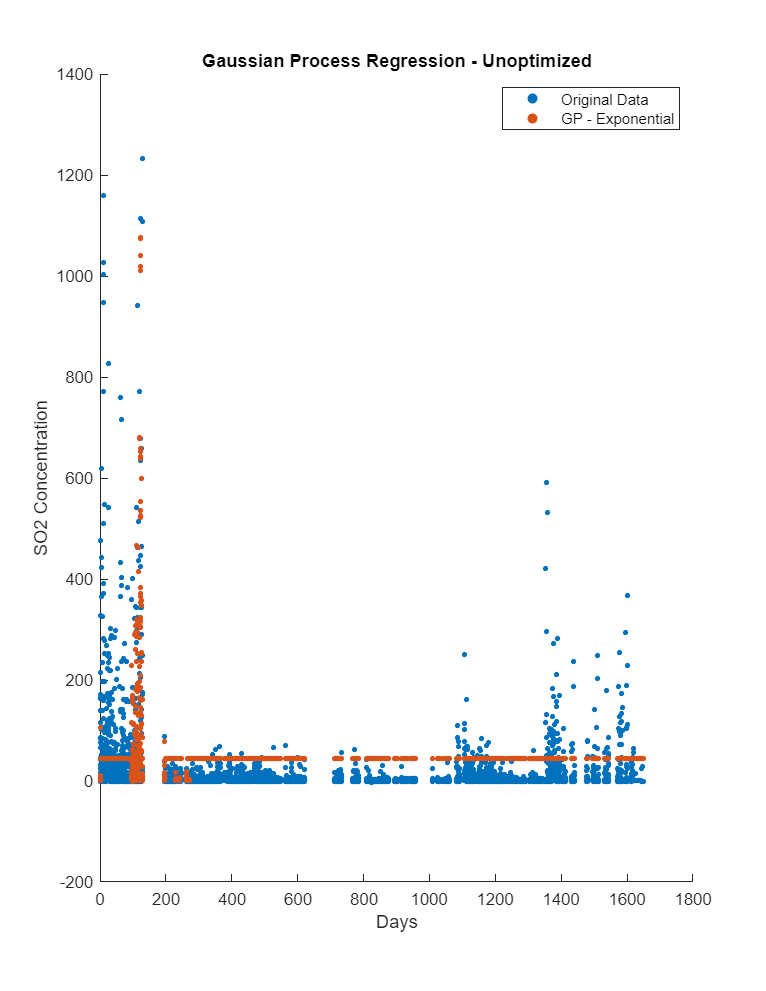

fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_1, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Unoptimized')
legend('Original Data', 'GP - Exponential')

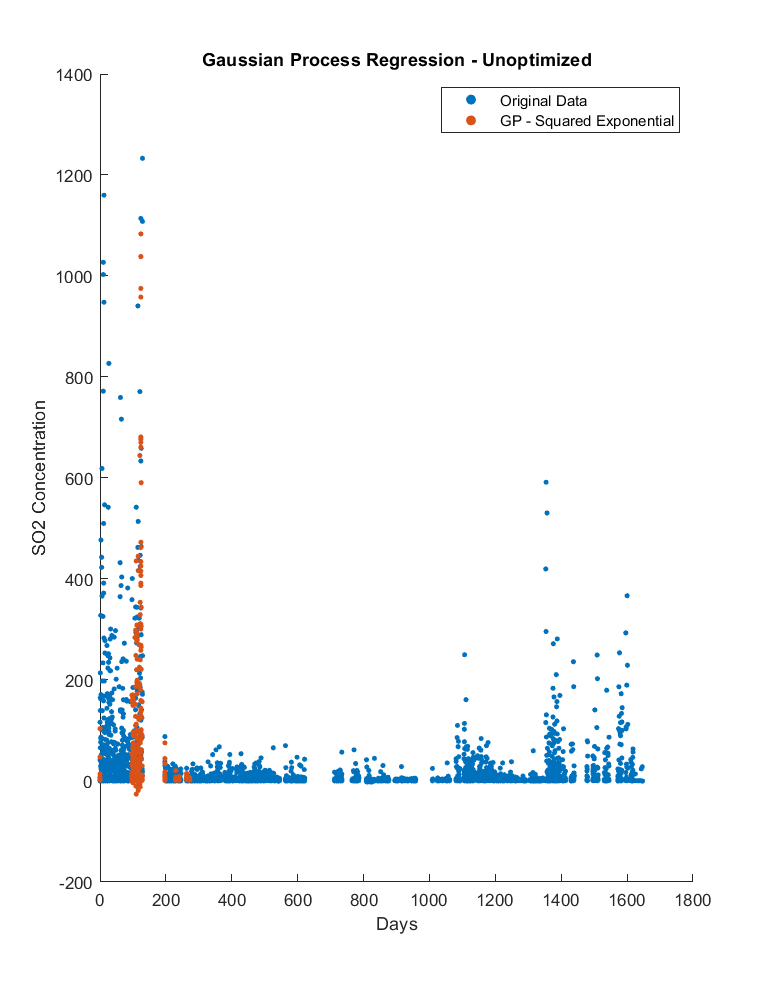

fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_2, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Unoptimized')
legend('Original Data', 'GP - Squared Exponential')

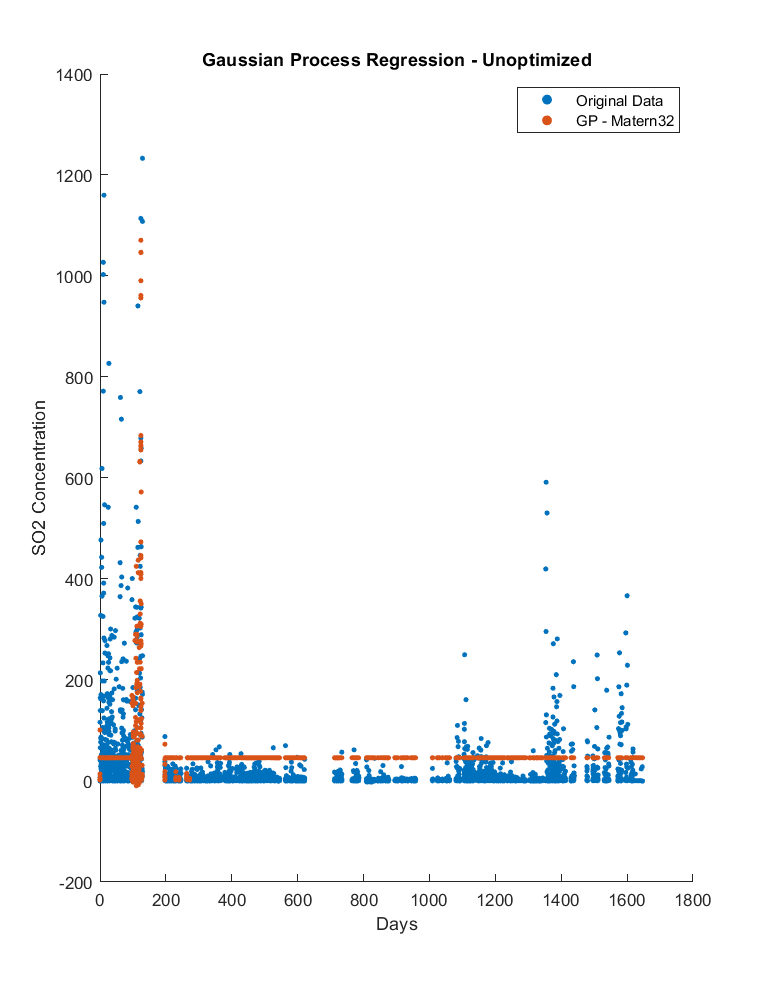

fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_3, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Unoptimized')
legend('Original Data', 'GP - Matern32')

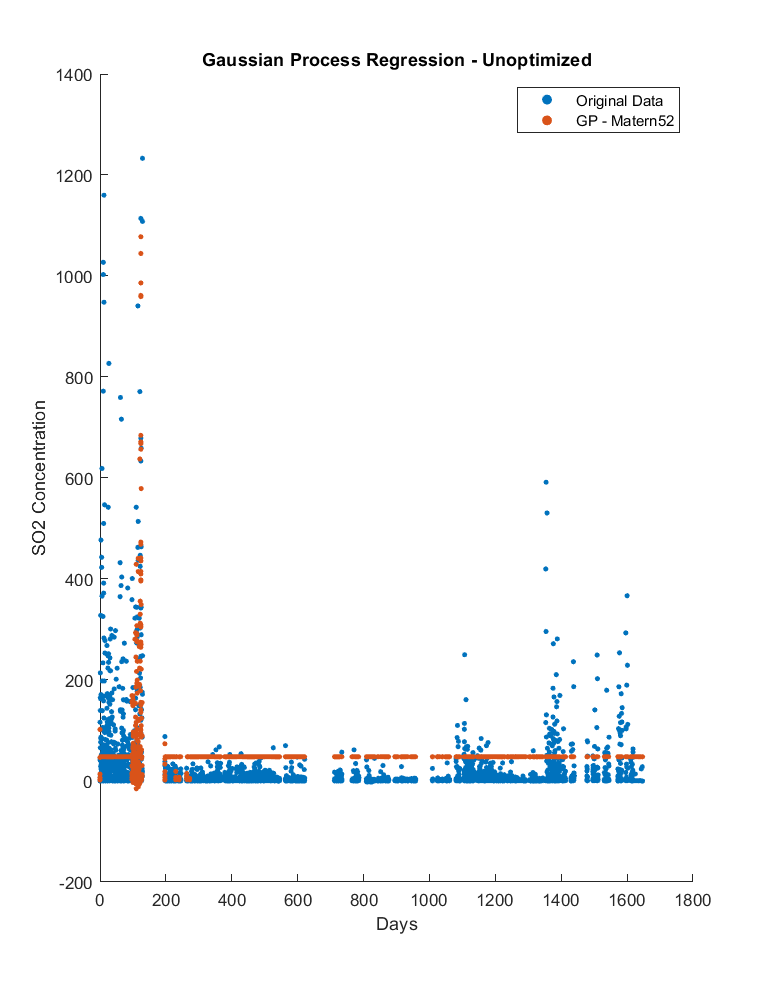

fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_4, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Unoptimized')
legend('Original Data', 'GP - Matern52')

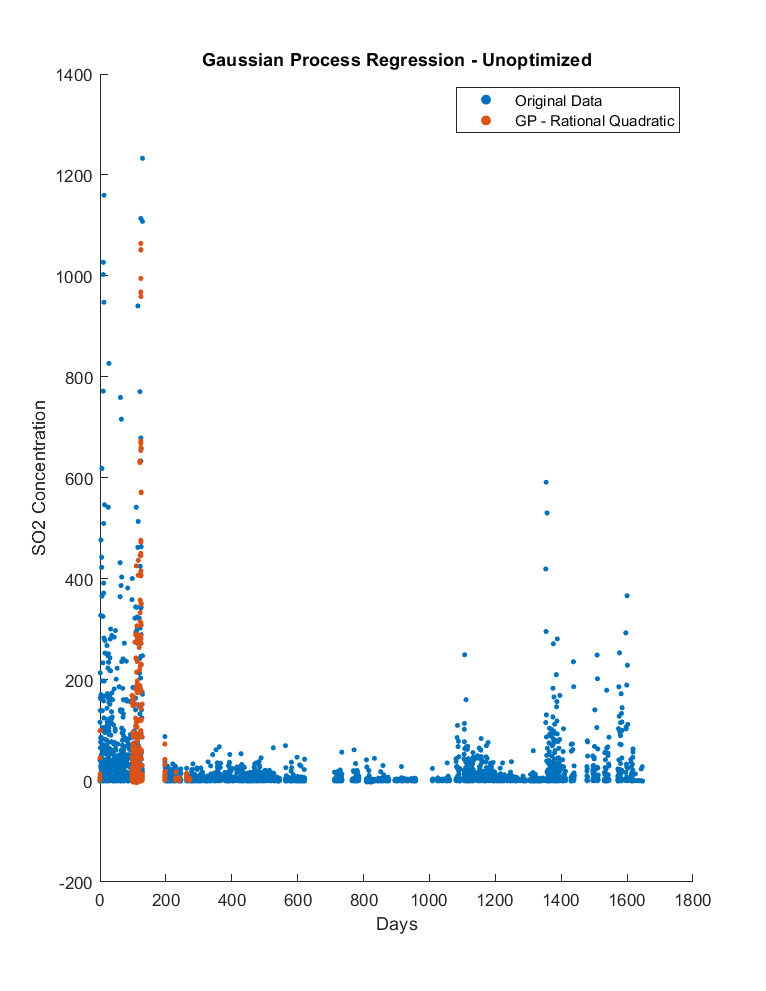

fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_5, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Unoptimized')
legend('Original Data', 'GP - Rational Quadratic')

### Train Gaussian Process with Various Kernels - Optimized

% Fit Gaussian Process with exponential Kernel
gprMdl_1a = fitrgp(x_train, y_train,'KernelFunction','exponential',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |        Sigma |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      8.5898 |      9.3821 |      8.5898 |      8.5898 |       501.84 |
|    2 | Best   |      8.3239 |      7.0095 |      8.3239 |      8.3773 |        10.33 |
|    3 | Accept |      8.3313 |      8.2848 |      8.3239 |      8.3449 |      0.22572 |
|    4 | Accept |      8.3353 |      8.3745 |      8.3239 |      8.3458 |    0.0017491 |
|    5 | Best   |      8.3141 |      8.4667 |      8.3141 |      8.3142 |       14.149 |
|    6 | Accept |      8.3352 |      8.5401 |      8.3141 |      8.3142 |     0.022345 |
|    7 | Accept |      8.3356 |      8.3734 |      8.3141 |      8.3168 |    0.0001808 |
|    8 | Accept |    

% Fit Gaussian Process with squared exponential Kernel
gprMdl_2a = fitrgp(x_train, y_train,'KernelFunction','squaredexponential',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |        Sigma |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      9.5249 |      9.3486 |      9.5249 |      9.5249 |   0.00037267 |
|    2 | Best   |      9.4829 |      6.9934 |      9.4829 |      9.4851 |       252.89 |
|    3 | Accept |      9.5249 |      9.6049 |      9.4829 |      9.4829 |     0.030423 |
|    4 | Accept |      9.5249 |      10.979 |      9.4829 |      9.4829 |      0.55945 |
|    5 | Accept |      9.8105 |      11.161 |      9.4829 |      9.5736 |       596.62 |
|    6 | Accept |      9.5249 |      9.2611 |      9.4829 |      9.5655 |      0.15356 |
|    7 | Accept |      9.5986 |      7.2933 |      9.4829 |      9.5702 |       10.624 |
|    8 | Accept |    


% Fit Gaussian Process with matern32 Kernel
gprMdl_3a = fitrgp(x_train, y_train,'KernelFunction','matern32',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

|======================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |        Sigma |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |      8.5542 |      9.9693 |      8.5542 |      8.5542 |       1.5109 |
|    2 | Accept |      8.5842 |      10.124 |      8.5542 |      8.5561 |   0.00051549 |
|    3 | Accept |      8.5842 |      10.087 |      8.5542 |      8.5622 |     0.044009 |
|    4 | Best   |      8.2918 |      6.7426 |      8.2918 |      8.2918 |       147.84 |
|    5 | Accept |      8.5891 |      8.9017 |      8.2918 |      8.5207 |       595.69 |
|    6 | Accept |      8.5842 |      10.075 |      8.2918 |      8.5313 |    0.0085076 |
|    7 | Best   |      8.2516 |      7.0918 | 

|    9 | Accept |      8.2166 |      8.2065 |      8.2108 |      8.2127 |        67.89 |
|   10 | Best   |      8.2066 |       7.711 |      8.2066 |      8.2072 |       80.917 |
|   11 | Best   |      8.2065 |      8.4836 |      8.2065 |      8.2069 |       86.304 |
|   12 | Accept |      8.5889 |      11.362 |      8.2065 |      8.2069 |       13.302 |
|   13 | Accept |      8.2066 |      8.3107 | 


% Fit Gaussian Process with matern52 Kernel
gprMdl_4a = fitrgp(x_train, y_train,'KernelFunction','matern52',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

% Fit Gaussian Process with rational quadratic Kernel
gprMdl_5a = fitrgp(x_train, y_train,'KernelFunction','rationalquadratic',...
    'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'));

### Predict for Testing Data

y_pred_train_1a = predict(gprMdl_1a, x_train);
y_pred_train_2a = predict(gprMdl_2a, x_train);
y_pred_train_3a = predict(gprMdl_3a, x_train);
y_pred_train_4a = predict(gprMdl_4a, x_train);
y_pred_train_5a = predict(gprMdl_5a, x_train);

### Calculate Performance Metrics

% Mean Squared Errors
MSE_1a = immse(y_pred_train_1a, y_train);
MSE_2a = immse(y_pred_train_2a, y_train);
MSE_3a = immse(y_pred_train_3a, y_train);
MSE_4a = immse(y_pred_train_4a, y_train);
MSE_5a = immse(y_pred_train_5a, y_train);
MSE_a = [MSE_1a, MSE_2a, MSE_3a, MSE_4a, MSE_5a];

% Average Least Absolute Error
LSE_1a = mean(abs(y_pred_train_1a - y_train));
LSE_2a = mean(abs(y_pred_train_2a - y_train));
LSE_3a = mean(abs(y_pred_train_3a - y_train));
LSE_4a = mean(abs(y_pred_train_4a - y_train));
LSE_5a = mean(abs(y_pred_train_5a - y_train));
LSE_a = [LSE_1a, LSE_2a, LSE_3a, LSE_4a, LSE_5a];

Metrics_a = cat(1, MSE_a, LSE_a);
Metrics_Table_a = array2table(Metrics_a, 'RowNames', {'MSE', 'LSE'}, 'VariableNames', {'Exponential', 'Squared Exponential', 'Matern32', 'Matern52','Rational Quadratic'});
disp(Metrics_Table_a)

### Plot Models

fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_1a, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Optimized')
legend('Original Data', 'GP - Exponential')
fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_2a, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Optimized')
legend('Original Data', 'GP - Squared Exponential')
fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_3a, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Optimized')
legend('Original Data', 'GP - Matern32')
fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_4a, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Optimized')
legend('Original Data', 'GP - Matern52')
fig = figure('Position', [0,0,850,1100]);
scatter(dates_train, y_train, 10, 'filled')
hold on
scatter(dates_train, y_pred_train_5a, 10, 'filled')
hold off
xlabel('Days')
ylabel('SO2 Concentration')
title('Gaussian Process Regression - Optimized')
legend('Original Data', 'GP - Rational Quadratic')

### Predict for Testing Data

% Testing_Data = readtable('Testing_Data.csv');
% Testing_Data.Date = [];
% 
% y_test = Testing_Data(:, 3);
% x_test = Test_Data(:, [1, 2, 4, 5, 6, 7, 8, 9, 10, 11]);
% y_pred_test = predict(gprMdl, x_test);
% 
% % 
% % % Select model with less RMSE
% % [~, I] = min(RMSE);
% % 
% % 
% % fig = figure('Position', [0,0,850,1100]);
% % for i = 1:12
% %     
% %    % Feature time vector for each hour
% %    time_interpolation(1:12,1) = time_range(i);
% %     
% %          for j = 1:12
% %              
% %              % Predict PM2.5 for each hour for every lat & lon combination
% %              pm2d5_interpolated(1:12,j) = predict(CVGPRMdl.Trained{I},[time_interpolation(:,1), Lat(:,j), Lon(:,j)]);
% %              
% %          end
% % 
% %     time_ = (i+9)/24;
% %     subplot(6,2,i)
% %     surf(Lon_to_Plot,Lat_to_Plot,pm2d5_interpolated)
% % 
% %     %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %     shading interp    
% %     view(0,90)
% %     xlabel('Longitude')
% %     ylabel('Latitude')
% %     c = colorbar;
% %     ylabel(c,'PM 2.5 (\mu g/m^3)')        
% %     title(datestr(time_,'HH:MM:SS'),'fontsize',10)
% % end